birdID = 'LUSMEG';
filename = 'common_nightingale_long_4.wav';

[audio, fs] = audioread(filename);
audio = mono(audio);

audio = stripSound(audio,fs,400);

[syllables, maxLength] = segmentSyllables(audio,fs);

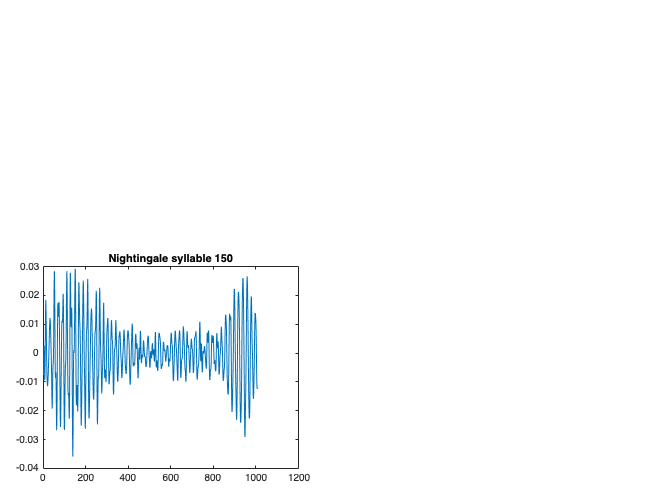

index = randi(size(syllables,1));
syllable = syllables{index,1};
plot(syllable)
title(sprintf('Nightingale syllable %d',index))

sound(syllable,fs);

for ii = 1:numel(syllables)
    syllable = cell2mat(syllables(ii));
    [~,wavFile,~] = fileparts(filename);
    fname = sprintf('./samples/syllables/%s/%s_%d.wav',birdID,wavFile,ii);
    audiowrite(fname,syllable,fs);
end